# Script to evaluate the effect of forces applied at the M1 FAN nodes on the M1 & M2 rigid-body motions

## Preamble

clearvars;
% Set telescope structural dynamics damping
sysDamp = 0.02;
% Flag to include M1 CG forces feedback
m1_FBc = false;%true;%

### Structural model folder

ModelFolder = '20210315_1728_MT_mount_v202102_M1_fans_OSSOnly'; %Locked-rotor model
% ModelFolder = '20210326_1803_MT_mount_v202102_M1_fans_OSSOnly';

## Load telescope structural model

FileName = fullfile(im.lfFolder,ModelFolder,"modal_state_space_model.mat");
if(~exist('outputTable','var') || 0)
    try
        fprintf("Loading modal model parameters from \n%s\n",FileName);
        load(FileName,'inputs2ModalF','modalDisp2Outputs',...
            'eigenfrequencies','inputTable','outputTable');
        
        % Handle modal parameters
        om2 = (eigenfrequencies(:)*2*pi).^2;
        proportionalDampingVec = sysDamp*ones(size(eigenfrequencies(:)));
        twice_zom = 2*proportionalDampingVec(:).*om0;
        
        % State-space model matrices
        B = [zeros(size(inputs2ModalF));inputs2ModalF];
        C = [modalDisp2Outputs,zeros(size(modalDisp2Outputs))];
        
        nm = size(inputs2ModalF,1);
        A = sparse([zeros(nm),eye(nm);-diag(om2), -diag(twice_zom)]);
        
    catch ME
        fprintf("Loading state-space model from \n%s\n",FileName);
        load(FileName,'A','B','C','inputTable','outputTable');

        % Retrieve modal-form parameters
        [aux,temp] = spdiags(A);
        om2 = -aux(1:temp(end),1);      % Vector of squared eigenfrequencies
        twice_zom = sqrt(om2).*sysDamp; % Vector of 2*damp*om
    end
end

Model maximum frequency (Hz)

max_model_Fr = 300;

Keep modes just up to frequency <max_model_Fr>

if(~isempty(max_model_Fr))
    clear A;
    [~,i_trim] = min(abs(sqrt(om2)/2/pi - max_model_Fr));
    om2 = om2(1:i_trim);
    twice_zom = twice_zom(1:i_trim);
    % Adjust SS model matrices
    A = sparse([zeros(i_trim),speye(i_trim);...
        -diag(om2), -diag(twice_zom)]);
    B = [zeros(i_trim,size(B,2));B(temp(end)+1:temp(end)+i_trim,:)];
    C = [C(:,1:i_trim),zeros(size(C,1),i_trim)];
end

damp = sysDamp*ones(size(om2));

## Extract subsystem with relevant IOs

% M1 FAN inputs
in = inputTable{'OSS_M1_fans_lcl_6F',"indices"}{1};
% M1/M2 RBM
m1out = outputTable{'OSS_M1_lcl','indices'}{1};
try m2out = outputTable{'MC_M2_RB_6D','indices'}{1};
catch, m2out = outputTable{'MC_ASM_COG_6D','indices'}{1};
end

b_ = B(:,in);
c1_ = C(m1out,:);
c2_ = C(m2out,:);

Compute static gains

K1 = c1_(:,1:nm) * diag(1./om2) * b_(nm+1:end,:);
K2 = c2_(:,1:nm) * diag(1./om2) * b_(nm+1:end,:);

## Results

### DC gain plot

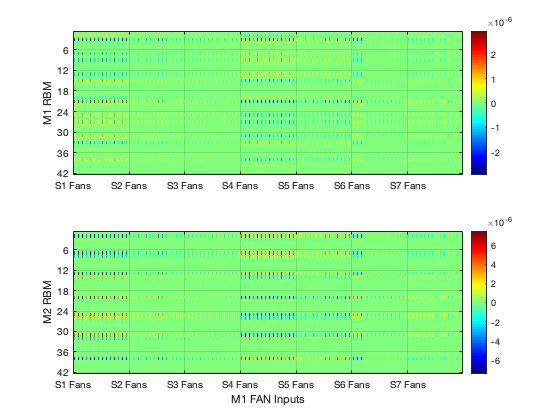

subplot(211)
imagesc(K1)
ylabel('M1 RBM')
colormap('turbo')
colorbar
xticks(1:6*14:7*6*14)
xticklabels({'S1 Fans','S2 Fans','S3 Fans',...
    'S4 Fans','S5 Fans','S6 Fans','S7 Fans'})
yticks(0:6:42)
grid on;
subplot(212)
imagesc(K2)
ylabel('M2 RBM')
xlabel('M1 FAN Inputs')
colormap('jet')
colorbar
xticks(1:6*14:7*6*14)
xticklabels({'S1 Fans','S2 Fans','S3 Fans',...
    'S4 Fans','S5 Fans','S6 Fans','S7 Fans'})
yticks(0:6:42)
grid on

### Segment-wise plot

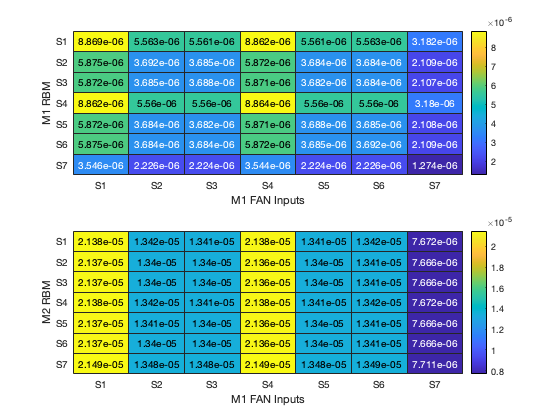

K1g = groupMatrix(6,6*14,K1);
subplot(211)
h1 = heatmap(K1g);
h1.XLabel = 'M1 FAN Inputs';
h1.YLabel = 'M1 RBM';
h1.XData = {'S1','S2','S3','S4','S5','S6','S7'};
h1.YData = {'S1','S2','S3','S4','S5','S6','S7'};
K2g = groupMatrix(6,6*14,K2);
subplot(212)
h2 = heatmap(K2g);
h2.XLabel = 'M1 FAN Inputs';
h2.YLabel = 'M2 RBM';
h2.YData = {'S1','S2','S3','S4','S5','S6','S7'};
h2.XData = {'S1','S2','S3','S4','S5','S6','S7'};
colormap default

Auxiliary function to grouping matrices

function phi = groupMatrix(n_rows, n_cols, matrix)
[nr, nc] = size(matrix);
if ((n_rows ~= 0) && (n_cols ~= 0))
    phi = zeros([nr/n_rows, nc/n_cols]);
    v_rows = ones(1,n_rows) * n_rows;
    v_cols = ones(1,n_cols) * n_cols;
    for i = 0:(nr/n_rows - 1)
        for j = 0:(nc/n_cols - 1)
            phi(i+1, j+1) = norm(matrix((1:n_rows) + i*v_rows, (1:n_cols) + j*v_cols));
        end
    end
end

%% Only Group Columns
if n_rows == 0
    phi = zeros([nr, nc/n_cols]);
    v_cols = ones(1,n_cols) * n_cols;
    for i = 0:(nr-1)
        for j = 0:(nc/n_cols - 1)
            phi(i+1, j+1) = norm(matrix(i+1,(1:n_cols) + j*v_cols));
        end
    end
end

%% Only Group Rows
if n_cols == 0
    phi = zeros([nr/n_rows, nc]);
    v_rows = ones(1,n_rows) * n_rows;
    
    for i = 0:(nr/n_rows - 1)
        for j = 0:(nc-1)
            phi(i+1, j+1) = norm(matrix((1:n_rows) + i*v_rows, j + 1));
        end
    end
end
end